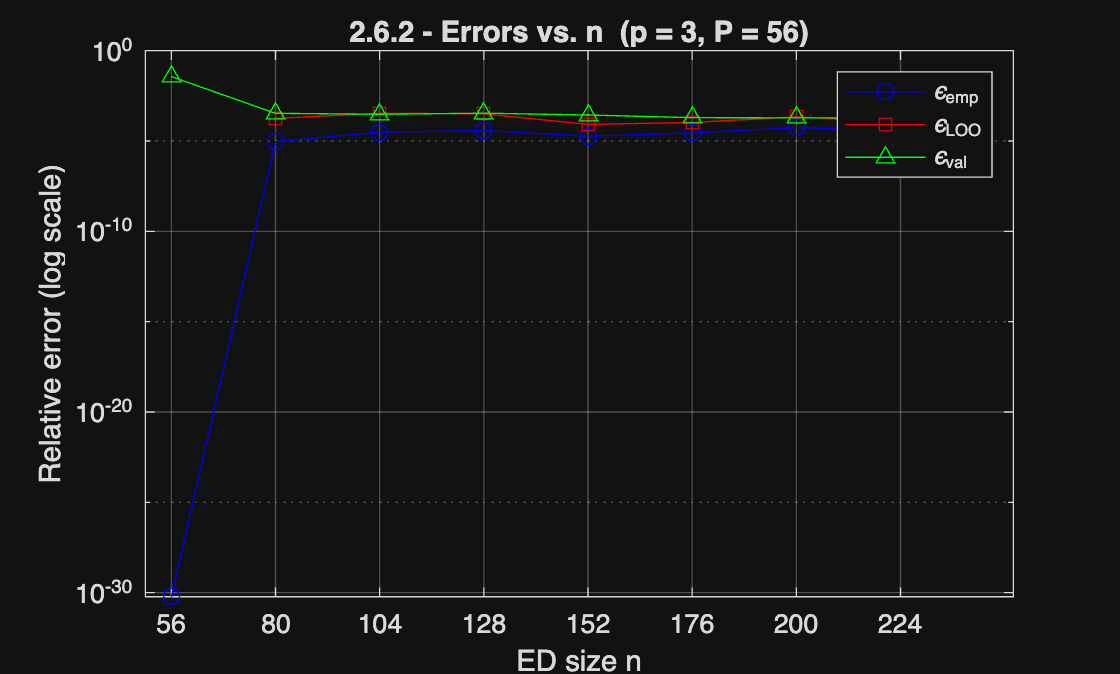

M = numel(params);
p = 3;
alphas = create_alphas(M, p);
P_card = size(alphas, 1);  % = 56

% Reference moments for 2.6.3
mu_ref  = mean(Y_val);
var_ref = var(Y_val);

% n sweep from P to 4*P in 8 steps
n_vals = unique(round(linspace(P_card, 4*P_card, 8)));

% Storage for 2.6.2
eps_emp_v = zeros(size(n_vals));
eps_loo_v = zeros(size(n_vals));
eps_val_v = zeros(size(n_vals));

% Storage for 2.6.3
err_mu_v  = zeros(size(n_vals));
err_var_v = zeros(size(n_vals));

for k = 1:numel(n_vals)
    n = n_vals(k);
    
    % Fresh ED for each n
    [X_ED, Y_ED] = sampleED(n, params, @riverDischarge);
    
    % Build PCE (shared for both 2.6.2 and 2.6.3)
    Xi_ED     = isoTransform(X_ED, params);
    Psi       = buildPsi(Xi_ED, alphas, params);
    c         = computeCoeffs(Psi, Y_ED);
    Y_PCE_val = evalPCE(X_val, c, alphas, params);
    
    %% 2.6.2 - Global errors
    [eps_emp_v(k), eps_loo_v(k), eps_val_v(k)] = ...
        computeErrors(Psi, Y_ED, c, Y_val, Y_PCE_val);
    
    %% 2.6.3 - Moments from coefficients (orthonormality property)
    % mean = constant term c(1)
    % var  = sum of squared non-constant coefficients
    mu_PCE  = c(1);
    var_PCE = sum(c(2:end).^2);
    
    err_mu_v(k)  = abs(mu_PCE  / mu_ref  - 1);
    err_var_v(k) = abs(var_PCE / var_ref - 1);
end

%% 2.6.2 - Plot errors vs. n
figure;
semilogy(n_vals, eps_emp_v, 'b-o'); hold on;
semilogy(n_vals, eps_loo_v, 'r-s');
semilogy(n_vals, eps_val_v, 'g-^'); hold off;
xlabel('ED size n');
ylabel('Relative error (log scale)');
title(sprintf('2.6.2 - Errors vs. n  (p = %d, P = %d)', p, P_card));
legend('\epsilon_{emp}', '\epsilon_{LOO}', '\epsilon_{val}');
grid on; xticks(n_vals);

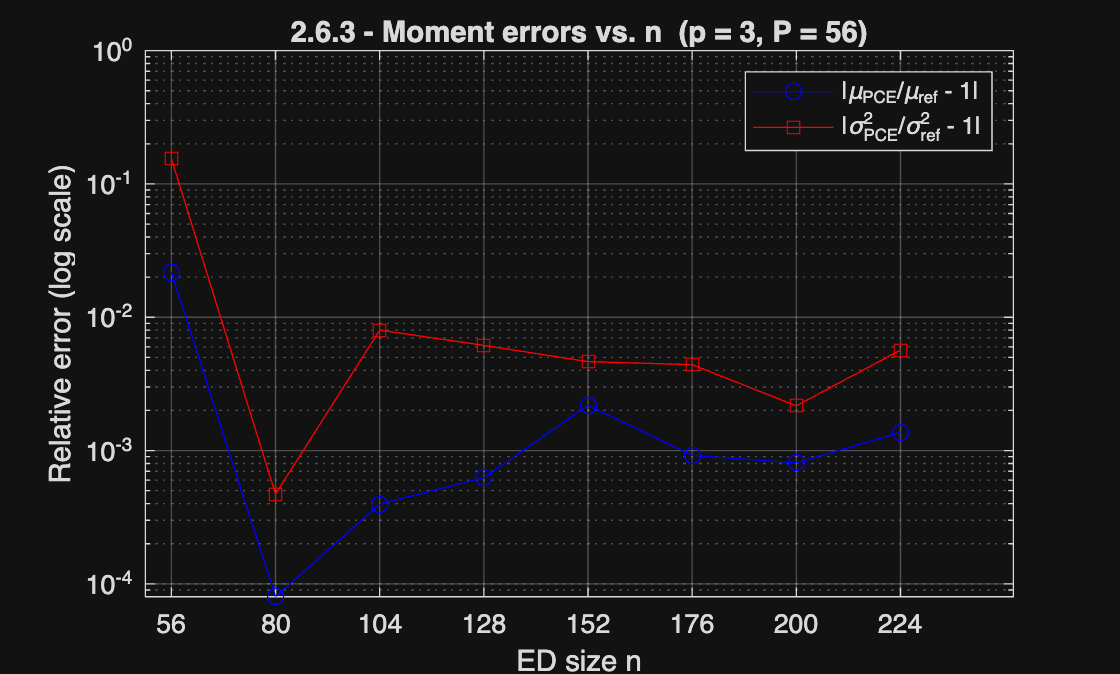


%% 2.6.3 - Plot moment errors vs. n
figure;
semilogy(n_vals, err_mu_v,  'b-o'); hold on;
semilogy(n_vals, err_var_v, 'r-s'); hold off;
xlabel('ED size n');
ylabel('Relative error (log scale)');
title(sprintf('2.6.3 - Moment errors vs. n  (p = %d, P = %d)', p, P_card));
legend('|\mu_{PCE}/\mu_{ref} - 1|', '|\sigma^2_{PCE}/\sigma^2_{ref} - 1|');
grid on; xticks(n_vals);